datapath = [pwd filesep 'preprocessedData'];
ds = fileDatastore(datapath,"ReadFcn",@load)

ds =   FileDatastore with properties:

                       Files: {
                              ' .../MatlabProjects/PricePrediction/preprocessedData/AABA_5395.mat';
                              ' .../MatlabProjects/PricePrediction/preprocessedData/AAMC_1142.mat';
                              ' .../MatlabProjects/PricePrediction/preprocessedData/AAME_2555.mat'
                               ... and 4622 more
                              }
                     Folders: {
                              '/home/christoph/MatlabProjects/PricePrediction/preprocessedData'
                              }
                 UniformRead: 0
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @load
      SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "og

numfiles = length(ds.Files);
predictors = cell(1);
responses = cell(1);

Move data from files to two big cell arrays (predictors and responses)

Time steps are given by columns, feature dimensions are given by rows -> data is transposed

Data is also normalized

for i = 1:numfiles

    if ~mod(i,250)
        fprintf("%i / %i\n",i,numfiles);
    end
    
    data = read(ds).data;
    
    if size(data,1) < 5000
        continue
    end
    
    predictors{end+1,1} = table2array(data(:,1:end-1))';
    responses{end+1,1} = table2array(data(:,end))';

end

250 / 4625
500 / 4625
750 / 4625
1000 / 4625
1250 / 4625
1500 / 4625
1750 / 4625
2000 / 4625
2250 / 4625
2500 / 4625
2750 / 4625
3000 / 4625
3250 / 4625
3500 / 4625
3750 / 4625
4000 / 4625
4250 / 4625
4500 / 4625



predictors = predictors(2:end)

predictors = 319×1 cell array
    {7×5395  double}
    {7×8299  double}
    {7×11942 double}
    {7×5651  double}
    {7×8688  double}
    {7×8099  double}
    {7×7811  double}
    {7×8353  double}
    {7×8688  double}
    {7×8678  double}
    {7×8108  double}
    {7×8285  double}
    {7×12036 double}
    {7×6607  double}
    {7×10246 double}
    {7×8335  double}


responses = responses(2:end)

responses = 319×1 cell array
    {1×5395  double}
    {1×8299  double}
    {1×11942 double}
    {1×5651  double}
    {1×8688  double}
    {1×8099  double}
    {1×7811  double}
    {1×8353  double}
    {1×8688  double}
    {1×8678  double}
    {1×8108  double}
    {1×8285  double}
    {1×12036 double}
    {1×6607  double}
    {1×10246 double}
    {1×8335  double}


Sort sequences by length

seqLength = cellfun(@(x) size(x,2),responses);
[seqLengthSorted, sortIdx] = sort(seqLength)

seqLengthSorted =         5009
        5010
        5034
        5098
        5107
        5115
        5187
        5197
        5211
        5226


sortIdx =    259
    63
   318
   254
   143
    24
    64
   288
    91
   209


predictors = predictors(sortIdx(end))

predictors = 1×1 cell array
    {7×14021 double}


responses = responses(sortIdx(end))

responses = 1×1 cell array
    {1×14021 double}


Plot sequence lenghts before and after sorting

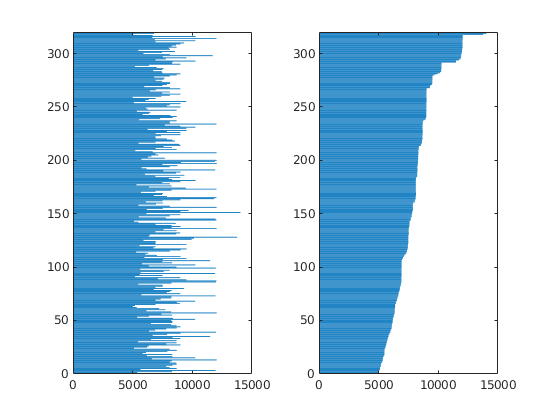

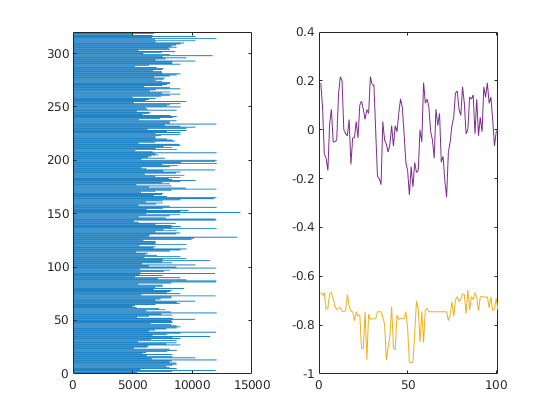

figure;
subplot(1,2,1);
barh(seqLength);
subplot(1,2,2);
barh(seqLengthSorted);

Split data into training, validation and testing

% cvpart = cvpartition(size(responses,1),'HoldOut',0.1);
%     XTrain = predictors(~cvpart.test);
%     YTrain = responses(~cvpart.test);
% XTestVal = predictors(cvpart.test);
% YTestVal = responses(cvpart.test);
% cvpart = cvpartition(size(XTestVal,1),'HoldOut',1);
%     XTest = XTestVal(cvpart.test);
%     YTest = YTestVal(cvpart.test);
%     XVal = XTestVal(~cvpart.test);
%     YVal = YTestVal(~cvpart.test);


predictorDims = size(XTrain{1},1);
featureDims = size(YTrain{1},1);
layers = [
    sequenceInputLayer(predictorDims,'Normalization',"zerocenter");
    bilstmLayer(128,'OutputMode',"sequence");
    dropoutLayer(0.2);
    bilstmLayer(64,'OutputMode',"sequence");
    dropoutLayer(0.2);
    fullyConnectedLayer(64);
    fullyConnectedLayer(featureDims);
    regressionLayer()]

layers =   8x1 Layer array with layers:

     1   ''   Sequence Input      Sequence input with 7 dimensions
     2   ''   BiLSTM              BiLSTM with 128 hidden units
     3   ''   Dropout             20% dropout
     4   ''   BiLSTM              BiLSTM with 64 hidden units
     5   ''   Dropout             20% dropout
     6   ''   Fully Connected     64 fully connected layer
     7   ''   Fully Connected     1 fully connected layer
     8   ''   Regression Output   mean-squared-error

Setup training options

opts = trainingOptions("adam", ...
    "MaxEpochs",3000, ...
    "MiniBatchSize",128, ...
    "SequenceLength","shortest", ...
    "SequencePaddingDirection","left", ...
    "InitialLearnRate",0.25, ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.98, ...
    "LearnRateDropPeriod",3, ...
    "Shuffle","never", ...
    'GradientThreshold',1, ...
    "Plots","training-progress")

opts =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 0.2500
             LearnRateSchedule: 'piecewise'
           LearnRateDropFactor: 0.9800
           LearnRateDropPeriod: 3
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: 1
                     MaxEpochs: 3000
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'never'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training

%     'ValidationData',{XVal YVal}, ...
%     'ValidationFrequency',20, ...
%     "ValidationPatience",1000, ...

Setup and train the network

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:02 |         1.82 |          1.7 |          0.2500 |


|      50 |          50 |       00:01:13 |         1.99 |          2.0 |          0.1809 |


|      77 |          77 |       00:01:53 |         1.85 |          1.7 |          0.1509 |
|========================================================================================|


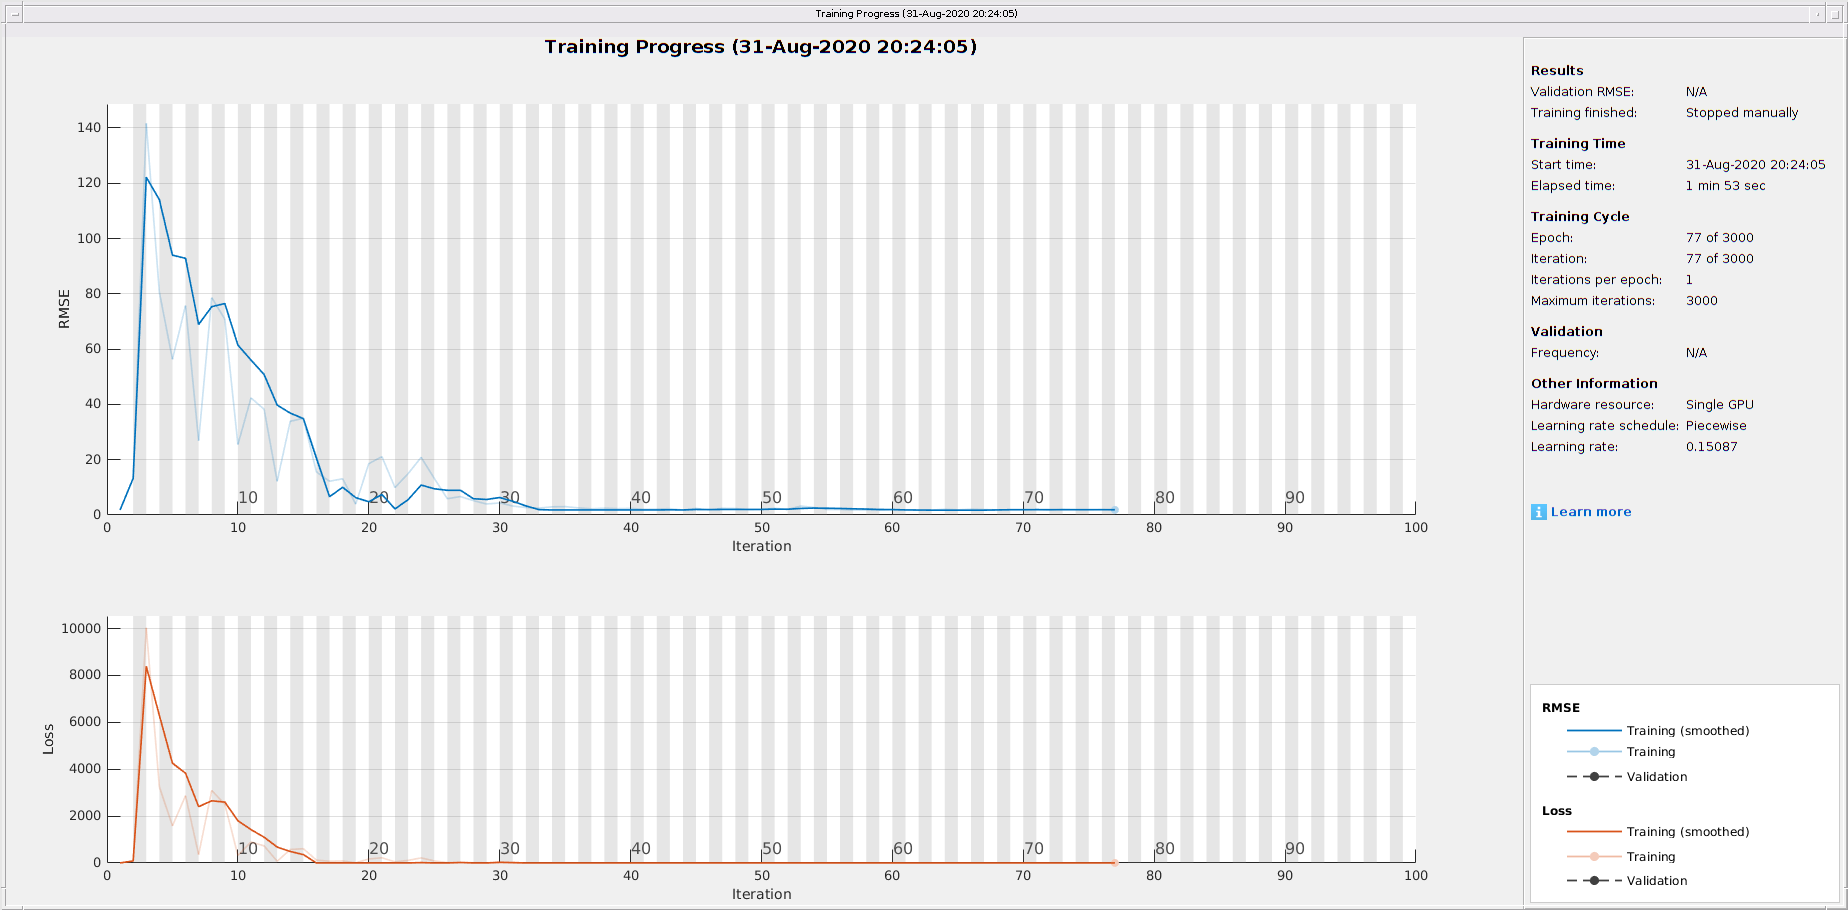

net =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


info = struct with fields:
     TrainingLoss: [1×77 double]
     TrainingRMSE: [1×77 double]
    BaseLearnRate: [1×77 double]


[net,info] = trainNetwork(predictors,responses,layers,opts)

save('BYPPNet_2','info','net')
net2 = resetState(net);

[net2, resps] = predictAndUpdateState(net2,predictors)

net2 =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


resps = 1×1 cell array
    {1×14021 single}


P = resps{1}

P = 1×14021 single row vector
   -1.4549   -1.5294   -1.5349   -1.3159   -1.4785   -1.4330   -1.4342   -1.4465   -1.6081   -1.6568   -1.6526   -1.6443   -1.6398   -1.6386   -1.6228   -1.6644   -1.6648   -1.6487   -1.6403   -1.6246   -1.6221   -1.6863   -1.6737   -1.6726   -1.6818   -1.6971   -1.6923   -1.6870   -1.6847   -1.6808   -1.6639   -1.6553   -1.6642   -1.6688   -1.6572   -1.6628   -1.6903   -1.6589   -1.6944   -1.6572   -1.6729   -1.6141   -1.5883   -1.6228   -1.7048   -1.7047   -1.6583   -1.6857   -1.6561   -1.2556


R = responses{1}

R =    -0.0586   -0.1088   -0.0166   -0.0502    0.0085         0    0.0923    0.1333    0.1001    0.0330    0.0087    0.0332    0.0753    0.0418    0.0338   -0.0251   -0.0252         0    0.0334    0.0084   -0.0168   -0.1001   -0.0416   -0.0416   -0.0919   -0.0837   -0.1002   -0.0417   -0.1505   -0.2841   -0.2509   -0.0500    0.0917    0.1254    0.0167   -0.0501   -0.1168   -0.0496    0.0170    0.1002    0.0080    0.0166   -0.0163   -0.0080   -0.0752   -0.2092   -0.3679   -0.6428   -0.4172   -0.1418


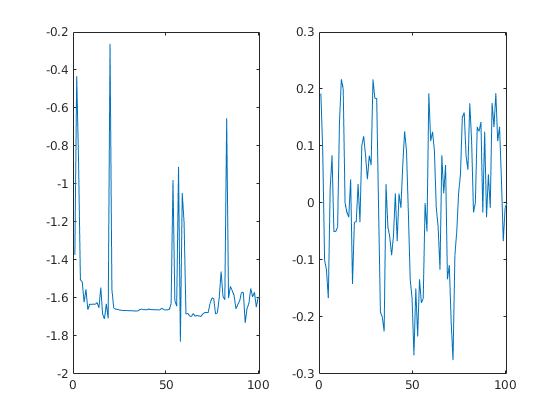

figure
subplot(121)
plot(P(100:200));
subplot(122)
plot(R(100:200))